# Optional: Benchmarking different activation functions

In class, we didn't have time to see how different activation functions perform when benchmarked side-by-side. Let's compare three neural networks that use all three different activation functions, and see which one performs the best.

## Training the three neural networks with different activation functions

clearvars -except logisticCM;
rng('default');

% Load the dataset
[Xtrain, Ytrain, Xtest, Ytest] = loadCancerData();

% Set default parameters
numOfActiveNodes = 2;
alpha = 0.05;
epoch = 500;
actFnc = 'Sigmoid';
randomstate = true;

% Train three different neural networks with different activation functions
logisticAF  = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'Sigmoid', randomstate);
ReLUAF      = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'ReLU', randomstate);
LeakyReLUAF = SNN(Xtrain, Ytrain, numOfActiveNodes, alpha, epoch, 'Leaky ReLU', randomstate);

## Evaluate the costs between models

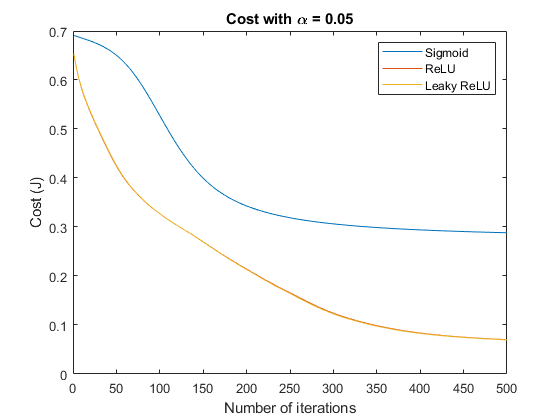

% Plot how they impact the cost
figure;
plot(1:length(logisticAF.J), logisticAF.J); hold on;
plot(1:length(ReLUAF.J), ReLUAF.J); hold on;
plot(1:length(LeakyReLUAF.J), LeakyReLUAF.J); hold on;
title('Cost with \alpha = 0.05');
xlabel('Number of iterations');
ylabel('Cost (J)');
legend('Sigmoid', 'ReLU', 'Leaky ReLU');

As you can see in the plot with the cost over the number of epochs, the ReLU and Leaky ReLU have very similar performances in this dataset. The sigmoid activation function converges to a minimum cost value sooner than the ReLU functions. However, the ReLU functions are able to achieve a much lower cost than the sigmoid activation function. This shows that the ReLU and the leaky ReLU are generally much better activation functions to use in practice.

## Benchmark each model using 10-fold cross validation

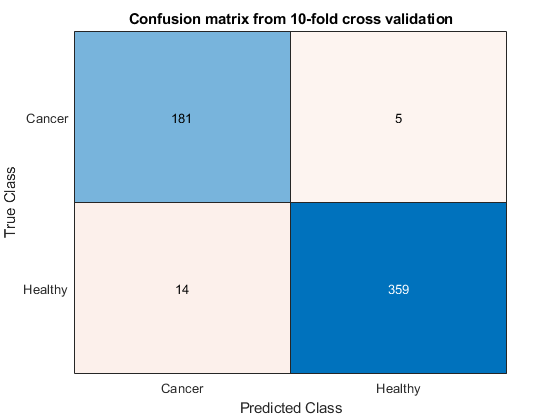

% Plot how they impact 10-fold cross validation accuracy
ypred_sigmoid = predict(logisticAF, Xtest, Ytest, 'SNN');
ypred_relu = predict(ReLUAF, Xtest, Ytest, 'SNN');
ypred_leaky = predict(LeakyReLUAF, Xtest, Ytest, 'SNN');

kfold = 10;
type  = 'SNN';

logistic = crossValidate(Xtrain, Ytrain, logisticAF, kfold, type);

disp(strcat('10-fold CV malignant classification accuracy: ', string(logistic.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.92424


disp(strcat('10-fold CV benign classification accuracy: ', string(logistic.healthyAccuracy)))

10-fold CV benign classification accuracy:0.98536


disp(strcat('10-fold CV average classification accuracy: ', string(logistic.averageClassAccuracy)))

10-fold CV average classification accuracy:0.96591


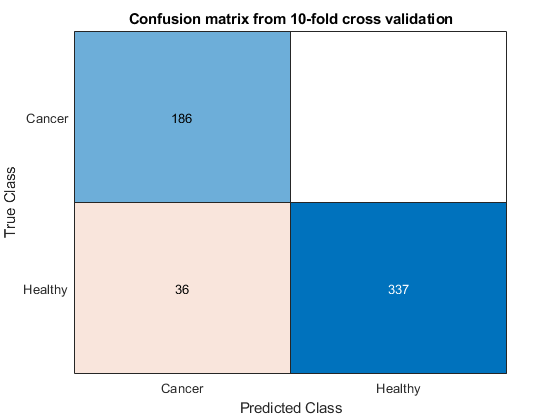

relu = crossValidate(Xtrain, Ytrain, ReLUAF, kfold, type);

disp(strcat('10-fold CV malignant classification accuracy: ', string(relu.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.82958


disp(strcat('10-fold CV benign classification accuracy: ', string(relu.healthyAccuracy)))

10-fold CV benign classification accuracy:1


disp(strcat('10-fold CV average classification accuracy: ', string(relu.averageClassAccuracy)))

10-fold CV average classification accuracy:0.93555


leaky = crossValidate(Xtrain, Ytrain, LeakyReLUAF, kfold, type);

disp(strcat('10-fold CV malignant classification accuracy: ', string(leaky.cancerAccuracy)))

10-fold CV malignant classification accuracy:0.82958


disp(strcat('10-fold CV benign classification accuracy: ', string(leaky.healthyAccuracy)))

10-fold CV benign classification accuracy:1


disp(strcat('10-fold CV average classification accuracy: ', string(leaky.averageClassAccuracy)))

10-fold CV average classification accuracy:0.93555
